clc
clear
close all

## Real Power Analysis

Pload

load('LOADS_advanced_control.mat');
load('LOSSES_advanced_control.mat');

% Aggregate 15-min results into hourly and compute statistics
scenarios = {'ev20','ev30','ev40'};
agg       = 4;    % number of 15-min intervals per hour
nHours    = 96/agg;

for i = 1:numel(scenarios)
    s = scenarios{i};

    %% 1) Build 15-min raw arrays
    raw3D_losses      = Plosses_cntrl.(s)/1000;                % [96×35×100] → kW
    P15_losses        = squeeze(sum(raw3D_losses,2));    % [96×100]
    P15_load          = squeeze(sum(Pload_cntrl.(s),2));      % [96×100]
    P15_total         = P15_load + P15_losses;           % [96×100]
    
    P15_Load.(s) = P15_load;
    %% 2) Down-sample to hourly by averaging each block of 4 rows
    % losses
    tmp = reshape(P15_losses,    agg, nHours, []);        % [4×24×100]
    P_hour_losses.(s) = squeeze(mean(tmp,1));            % [24×100]
    % load
    tmp = reshape(P15_load,      agg, nHours, []);        % [4×24×100]
    P_hour_load.(s)   = squeeze(mean(tmp,1));            % [24×100]
    % total
    tmp = reshape(P15_total,     agg, nHours, []);        % [4×24×100]
    P_hour_total.(s)  = squeeze(mean(tmp,1));            % [24×100]

    nRuns = size(P_hour_total.(s),2);

    %% 3) Hourly statistics (mean, std, p95)
    % losses
    powerLossesH.(s).mean =  mean(P_hour_losses.(s),2);
    powerLossesH.(s).std  =  std( P_hour_losses.(s),0,2);
    powerLossesH.(s).p95  =  prctile(P_hour_losses.(s),95,2);
    % load
    powerLoadH.(s).mean   =  mean(P_hour_load.(s),2);
    powerLoadH.(s).std    =  std( P_hour_load.(s),0,2);
    powerLoadH.(s).p95    =  prctile(P_hour_load.(s), 95,2);
    % total
    powerTotalH.(s).mean  =  mean(P_hour_total.(s),2);
    powerTotalH.(s).std   =  std( P_hour_total.(s),0,2);
    powerTotalH.(s).p95   =  prctile(P_hour_total.(s),95,2);

    %% 4) Hourly top-5% means
    for h = 1:nHours
        % losses
        vals = P_hour_losses.(s)(h,:); 
        cutoff = powerLossesH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerLossesH.(s).top5Mean(h,:) = mean(top5);
        % load
        vals = P_hour_load.(s)(h,:);
        cutoff = powerLoadH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerLoadH.(s).top5Mean(h,:) = mean(top5);
        % total
        vals = P_hour_total.(s)(h,:);
        cutoff = powerTotalH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerTotalH.(s).top5Mean(h,:) = mean(top5);
    end

    %% 5) Daily‐total energy per run (kWh)
    % Since each hourly bin is already average kW over 1 h, sum → kWh
    runE_losses = sum(P_hour_losses.(s),1);   % [1×100] kWh
    runE_load   = sum(P_hour_load.(s),  1);
    runE_total  = sum(P_hour_total.(s), 1);

    %% 6) 24 h aggregate statistics
    % losses
    powerLosses_24h.(s).mean     = mean(runE_losses);
    powerLosses_24h.(s).std      = std( runE_losses,0,2);
    powerLosses_24h.(s).p95      = prctile(runE_losses,95);
    powerLosses_24h.(s).top5Mean = sum(powerLossesH.(s).top5Mean);
    % load
    powerLoad_24h.(s).mean       = mean(runE_load);
    powerLoad_24h.(s).std        = std( runE_load,0,2);
    powerLoad_24h.(s).p95        = prctile(runE_load,95);
    powerLoad_24h.(s).top5Mean   = sum(powerLoadH.(s).top5Mean);
    % total
    powerTotal_24h.(s).mean      = mean(runE_total);
    powerTotal_24h.(s).std       = std( runE_total,0,2);
    powerTotal_24h.(s).p95       = prctile(runE_total,95);
    powerTotal_24h.(s).top5Mean  = sum(powerTotalH.(s).top5Mean);
end

save('statsPower_cntrl_advanced.mat', 'powerLoadH', 'powerLossesH', 'powerTotalH','P15_Load', ...
     'powerLoad_24h', 'powerLosses_24h', 'powerTotal_24h');

clearvars -except P_hour_total
load('statsPower_cntrl_advanced.mat')

## Plot the Pload for each scenario

%% ================== FIGURE SETUP (MANDATORY) ==================
close all; clc;

% Physical size for EPS (single-column journal)
figW = 18;   % cm
figH = 22;   % cm

figure('Units','centimeters',...
       'Position',[2 2 figW figH],...
       'Color','w',...
       'Renderer','painters');

% Global font control
set(groot,'defaultAxesFontSize',14);
set(groot,'defaultTextFontSize',14);
set(groot,'defaultAxesLineWidth',1.5);   % thicker axes
set(groot,'defaultLineLineWidth',2);

%% ================== DATA ==================
scenarios = {'ev20','ev30','ev40'};
hours     = 1:24;

peakHours = struct();

%% ================== LAYOUT ==================
tiledlayout(3,1,...
    'Padding','compact',...
    'TileSpacing','compact');

%% ================== PLOTTING ==================
for i = 1:numel(scenarios)

    s = scenarios{i};
    y = powerLoadH.(s).p95(:);     % [24x1]
    m = mean(y);

    % Shade only values above daily mean
    yshade = y;
    yshade(y < m) = NaN;

    nexttile; hold on;

    % Shaded peak area
    hA = area(hours, yshade, 'BaseValue', m);
    set(hA,'FaceAlpha',0.25,'EdgeColor','none');

    % Load profile
    plot(hours, y, 'k-');

    % Mean line
    yline(m,'r--',...
        sprintf('Mean = %.2f kW',m),...
        'LineWidth',1.2,...
        'LabelHorizontalAlignment','left');

    % Peak-hour indices
    peakHours.(s) = find(y > m);

    % ---------------- AXES FORMATTING ----------------
    ax = gca;
    ax.FontSize   = 14;
    ax.FontWeight = 'bold';      % bold tick labels
    ax.LineWidth  = 1.5;         % bold axes
    ax.XLim       = [0 25];
    ax.XTick      = 0:5:25;

    % Scenario-specific Y limits and ticks
    if strcmp(s,'ev40')
        ax.YLim  = [0 135];
        ax.YTick = [0:50:100 135];   % clean, non-overlapping
    else
        ax.YLim  = [0 120];
        ax.YTick = [0:50:100 120];
    end


    grid on; box on;

    xlabel('Time [h]','FontWeight','bold');
    ylabel('Load Power (kW)','FontWeight','bold');
    title(sprintf('Scenario: %s',lower(s)),...
          'FontWeight','bold');

end

%% ================== EXPORT ==================
print(gcf,'total_load_control.eps','-depsc2','-vector');

%% ================== OUTPUT ==================
disp('Peak hours (indices 1–24):');
disp(peakHours);


## Total daily Power Losses

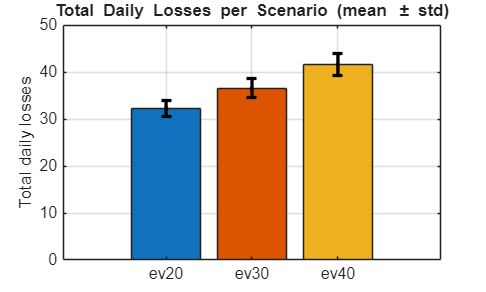

clear
load('statsPower_cntrl_advanced.mat', 'powerLossesH', 'powerLosses_24h');

scenarios = {'ev20','ev30','ev40'};        
colors = lines(numel(scenarios));

%Total Daily Losses
bar_vals = zeros(1,numel(scenarios));
err_std  = zeros(1,numel(scenarios));

for i = 1:numel(scenarios)
    s = scenarios{i};
    bar_vals(i) = powerLosses_24h.(s).mean;   % scalar [kWh or kW⋅h depending on your aggregation]
    err_std(i)  = powerLosses_24h.(s).std;    % same units as mean
end

figure; 
b = bar(1:numel(scenarios), bar_vals, 'FaceColor','flat'); hold on;
b.CData = lines(numel(scenarios));
errorbar(1:numel(scenarios), bar_vals, err_std, 'k.', 'LineWidth', 2);

set(gca, 'XTick', 1:numel(scenarios), 'XTickLabel', scenarios);
ylabel('Total daily losses');
title('Total Daily Losses per Scenario (mean \pm std)');
grid on;

clear
load('EV_data.mat');
load('EV_load_advanced_control.mat', 'EV_load_cntrl');

scenarios = {'ev20','ev30','ev40'};  % your scenarios
t = (0:95)*0.25;  % hours for 96×15-min steps

figure('Name','Total EV Load (Aggregated) p95','Color','w');
tiledlayout(numel(scenarios),1,'TileSpacing','compact');

for i = 1:numel(scenarios)
    s = scenarios{i};

    % --- Uncontrolled total load per MC ---
    Xu = EV_load_unctrl.(s);               % [T x B x MC]
    total_u = squeeze(sum(Xu, 2));         % sum over buses → [T x MC]

    % --- Controlled total load per MC ---
    Xc = EV_load_cntrl.(s);                 % [T x B x MC]
    total_c = squeeze(sum(Xc, 2));          % sum over buses → [T x MC]

    % --- p95 across MC runs ---
    p95_u = prctile(total_u, 95, 2);        % [T x 1]
    p95_c = prctile(total_c, 95, 2);        % [T x 1]

    % --- Plot ---
    nexttile; hold on; grid on;
    plot(t, p95_u, 'LineWidth', 1.6);
    plot(t, p95_c, '--', 'LineWidth', 1.8);
    xlabel('Time [h]'); ylabel('Total EV Load (p95)');
    title(sprintf('Scenario: %s', s));
    legend('Uncontrolled','Controlled','Location','best');
    xlim([0 24]);
end